# ΨΗΦΙΑΚΕΣ ΤΗΛΕΠΙΚΟΙΝΩΝΙΕΣ

## 1ο σετ Εργαστηριακών Ασκήσεων 

Λουδάρος Ιωάννης - ΑΜ 1067400

% Μεταφορά του Current Folder στον κατάλογο του αρχείου ώστε να υπάρχει
% πρόσβαση στις απαιτούμενες συναρτήσεις.

cd(fileparts(matlab.desktop.editor.getActiveFilename))

### Μέρος A

#### Η πηγή 

image = imread('parrot.png');

image_stream = reshape(image,1,[])

image_stream = 1×30000 uint8 row vector
     0     0     0    17     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    17    17    51   153   204   136    17     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


binary_image_stream = reshape((dec2bin(typecast(image(:),'uint8'),4)-'0').',1,[])

binary_image_stream =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


#### 1.a. Συχνότητα Εμφάνισης τιμών στο Μητρώο 

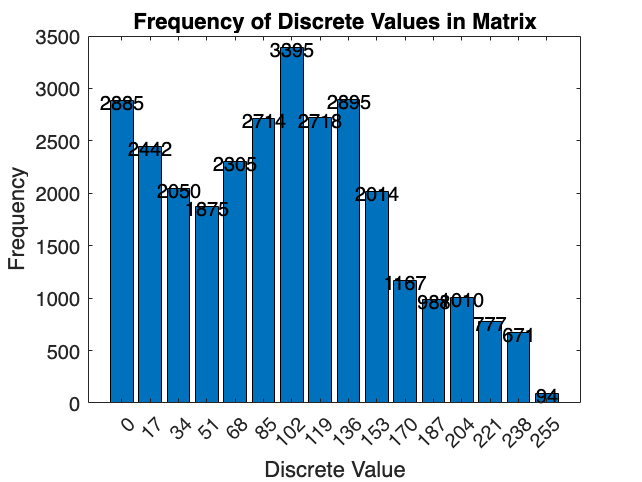

% Get the unique values in the matrix
unique_values = unique(image);

% Count the occurrences of each unique value
frequency = zeros(size(unique_values));
for i = 1:size(image, 1)
    for j = 1:size(image, 2)
        frequency(unique_values == image(i, j)) = frequency(unique_values == image(i, j)) + 1;
    end
end

% Create a bar graph to make the frequencies easily readable
bar(unique_values, frequency);
xticks(unique_values);
xticklabels(unique_values);
xlabel('Discrete Value');
ylabel('Frequency');
title('Frequency of Discrete Values in Matrix');

% Add labels to the top of each bar
for i = 1:size(unique_values,1)
    text(unique_values(i), frequency(i)+100, num2str(frequency(i)), ...
        'VerticalAlignment', 'top', 'HorizontalAlignment', ...
        'center');
end

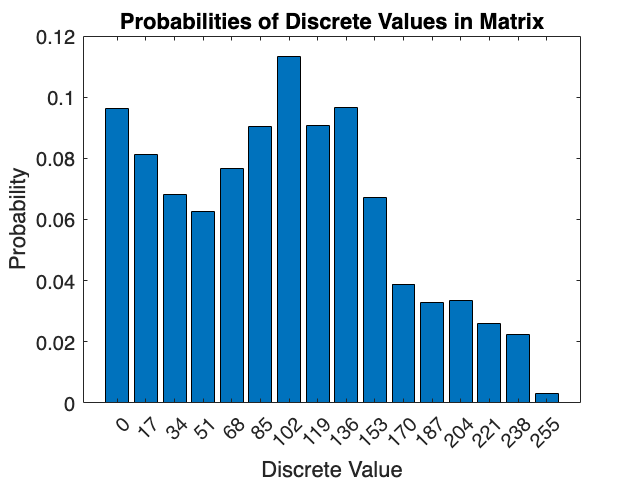

% Get the probability of each integer for the huffman dict later
probability = frequency./ (200*150);

% Create a bar graph to make the probabilities easily readable
bar(unique_values, probability);
xticks(unique_values);
xticklabels(unique_values);
xlabel('Discrete Value');
ylabel('Probability');
title('Probabilities of Discrete Values in Matrix');

#### 1.b. Κωδικοποίηση Huffman

% Create a dictionary for the encoding
[dict, avglen] = huffmandict(unique_values, probability)

dict = 16×2 cell array
    {[  0]}    {[        1 1 0]}
    {[ 17]}    {[      0 0 1 0]}
    {[ 34]}    {[      0 1 0 0]}
    {[ 51]}    {[      0 1 1 1]}
    {[ 68]}    {[      0 0 1 1]}
    {[ 85]}    {[      0 0 0 0]}
    {[102]}    {[        1 0 0]}
    {[119]}    {[        1 1 1]}
    {[136]}    {[        1 0 1]}
    {[153]}    {[      0 1 0 1]}
    {[170]}    {[    0 0 0 1 1]}
    {[187]}    {[    0 1 1 0 1]}
    {[204]}    {[    0 1 1 0 0]}
    {[221]}    {[  0 0 0 1 0 0]}
    {[238]}    {[0 0 0 1 0 1 0]}
    {[255]}    {[0 0 0 1 0 1 1]}


avglen = 3.8374


% Encode the Source
encoded_image_stream = huffmanenco(image_stream, dict);

% Compute the entropy
entropy = -sum(probability .* log2(probability))

entropy = 3.7831


% Copmute efficiency 
efficiency = entropy/avglen

efficiency = 0.9859

#### 2.a. Σύμβολα Δεύτερης Τάξης Επέκτασης Πηγής

% Finding the symbols 
% (all the possible permutations of unique_values).

new_symbols = zeros(size(unique_values,1)^2,2);
new_symbol_prob = zeros(size(unique_values,1)^2,1);
for j = 1 : size(unique_values)
    for k = 1 : size(unique_values)
        new_symbols((j-1)*size(unique_values,1)+k, :) = [unique_values(j) unique_values(k)];
        new_symbol_prob((j-1)*size(unique_values,1)+k) = probability(j)*probability(k);
    end
end

new_symbols

new_symbols =      0     0
     0    17
     0    34
     0    51
     0    68
     0    85
     0   102
     0   119
     0   136
     0   153


new_symbol_prob

new_symbol_prob =     0.0092
    0.0078
    0.0066
    0.0060
    0.0074
    0.0087
    0.0109
    0.0087
    0.0093
    0.0065


#### 2.b. Κωδικοποίηση Εικόνας

% Find the symbols that are actually used.
unique_pairs = [];
for i = 1 : 2 : size(image_stream,2)
    temp = [image_stream(i) image_stream(i+1)];
    

    % Does this pair already exists?
    flag = 0;
    for j = 1:size(unique_pairs,1)
        if j == 0
            break;
        else
            if temp == unique_pairs(j,:)
                flag = 1;
            end 
        end 
    end 

    % If not, add it

    if (~flag)
        unique_pairs = [unique_pairs; temp];
    end 
end

unique_pairs = sortrows(unique_pairs,[1,2])

unique_pairs = 178×2 uint8 matrix
     0     0
     0    17
     0    34
     0    51
     0    68
     0    85
     0   102
    17     0
    17    17
    17    34


           
% Find the frequency of the new symbols.
unique_pair_frequency = zeros(size(unique_pairs,1),1);
for i = 1:2:size(image_stream, 2)
    temp = [image_stream(i) image_stream(i+1)];
    
    for j = 1:size(unique_pairs,1)
        if unique_pairs(j,:) == temp
            unique_pair_frequency(j) = unique_pair_frequency(j)+1;
            break;
        end
    end
end    

unique_pair_frequency

unique_pair_frequency =         1232
         207
          18
           8
           2
           1
           2
         170
         752
         220



% Get the probability of each pair for the huffman dict later
unique_pair_probability = unique_pair_frequency./ ((200*150)/2)

unique_pair_probability =     0.0821
    0.0138
    0.0012
    0.0005
    0.0001
    0.0001
    0.0001
    0.0113
    0.0501
    0.0147


% Convert the previous stream to use the new symbols 
image_stream_converted = zeros(1,size(image_stream,2)/2);
for i = 1:2:size(image_stream, 2)
    temp = [image_stream(i) image_stream(i+1)];

    for j = 1:size(unique_pairs,1)
        if unique_pairs(j,:) == temp
            image_stream_converted(ceil(i/2)) = j;
            break;
        end
    end
end 

image_stream_converted

image_stream_converted =      1     2     1     1     1     1     1     1     1     1     1     1     9    40   151     8     1     1     1     1     1     1     1     1     1     1     1     1     1     9     9    54   155   143   108   122   119     8    27   142   107    81   145   104    82   121    94   105    21    67


% Create a dictionary for the encoding
[dict2, avglen2] = huffmandict(1:178, unique_pair_probability)

dict2 = 178×2 cell array
    {[ 1]}    {[                    0 0 0 1]}
    {[ 2]}    {[                1 0 1 0 0 1]}
    {[ 3]}    {[        0 0 0 0 1 1 1 1 1 0]}
    {[ 4]}    {[      0 1 0 1 0 0 1 1 0 0 1]}
    {[ 5]}    {[  0 1 0 1 0 0 1 1 1 0 1 0 0]}
    {[ 6]}    {[0 1 0 1 0 0 1 1 1 0 1 0 1 1]}
    {[ 7]}    {[  0 1 0 1 0 0 1 1 1 0 1 1 1]}
    {[ 8]}    {[              0 0 0 0 0 1 1]}
    {[ 9]}    {[                    1 1 0 1]}
    {[10]}    {[                0 1 1 1 0 1]}
    {[11]}    {[          0 0 0 0 1 0 0 0 1]}
    {[12]}    {[        0 1 1 1 1 0 1 0 0 0]}
    {[13]}    {[    1 1 0 0 0 1 0 1 0 0 1 1]}
    {[14]}    {[    0 0 0 0 1 1 0 0 0 0 0 1]}
    {[15]}    {[    0 1 0 1 0 0 1 0 0 0 0 0]}
    {[16]}    {[  0 1 0 1 0 0 1 1 1 0 1 1 0]}


avglen2 = 5.6412


% Encode the Source
encoded_image_stream_converted = huffmanenco(image_stream_converted, dict2);

% Compute the entropy
entropy2 = -sum(unique_pair_probability .* log2(unique_pair_probability))

entropy2 = 5.6147


% Copmute efficiency 
efficiency2 = entropy2/avglen2

efficiency2 = 0.9953

#### 3.a. Υπολογισμός Εντροπίας 

Όπως θίξαμε ήδη από την δεύτερη παράγραφο του ερωτήματος 2.a, η διαδικασία που ακολουθήσαμε δεν δημιούργησε ακριβώς την δεύτερης τάξης επέκταση πηγής του ερωτήματος 1, αλλά μια μικρότερη που περιέχει ένα υποσύνολο των συμβόλων της. Έτσι από τα 256 που θα έπρεπε να είναι κανονικά τα σύμβολα, συναντήσαμε μόνο 178.

#### 3.b. Φράγμα Μέσου Μήκους Κώδικα 

Το φράγμα για το μέσο μήκος όπως διατυπώνεται στις σημειώσεις του μαθήματος ισχύει και στις δύο πηγές.


$$H(X) \leq \bar{L} < H(X)+1$$


Δηλαδή :

$3.7831 \leq 3.8374< 4.7831$, που είναι αληθές, και 

$5.6147 \leq 5.6412< 6.6147$, που είναι επίσης αληθές.

#### 4. Επαλήθευση Κωδικοποίησης και Λόγος Συμπίεσης 

% Decode and validate
decoded_image_stream = huffmandeco(encoded_image_stream,dict);

check = all(image_stream == decoded_image_stream)

check = logical
   1


% Calculate Compression Rate
Compression_Rate = size(encoded_image_stream,2) / (size(image_stream,2)*4)

Compression_Rate = 0.9593


Compression_Rate_uint8 = size(encoded_image_stream,2) / (size(image_stream,2)*8)

Compression_Rate_uint8 = 0.4797

#### 5. Μετάδοση Σήματος μέσα από Κανάλι 

% Transmit through the channel
received = binary_symmetric_channel(encoded_image_stream);

% Calculate the p parameter for this transmission 
% (and the joint probabilities pxy)
counter = 0;
pxy = zeros(2,2);
px = zeros(2,1);
py = zeros(2,1);
for i = 1:size(received,2)
    if received(i) == encoded_image_stream(i)
        counter = counter + 1;
    end 
    received_bit = received(i);
    sent_bit = encoded_image_stream(i);

    pxy(sent_bit+1,received_bit+1) = pxy(sent_bit+1,received_bit+1) + 1;

    if encoded_image_stream(i)==0
        px(1)=px(1)+1;
    end

    if received(i)==0
        py(1)=py(1)+1;
    end
end

px(1) = px(1)/size(encoded_image_stream,2);
px(2) = 1 - px(1);

py(1) = py(1)/size(received,2);
py(2) = 1 - py(1);

px

px =     0.5519
    0.4481


py

py =     0.5398
    0.4602


pxy= pxy./size(encoded_image_stream,2)

pxy =     0.4868    0.0652
    0.0530    0.3950


p = counter / size(received,2)

p = 0.8818

% Calculate the Capacity of the Channel 
H = - p * log2(p) - (1-p)*log2(1-p)

H = 0.5242

C = 1 - H

C = 0.4758

% Mutual Information
MI=0;
for i = 1:2
    for j = 1:2
        MI = pxy(i,j) * log2((pxy(i,j)/px(i))/py(j));
    end
end

MI

MI = 0.3705